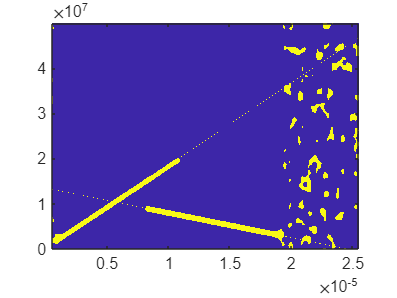

clear
clc

SNR = 20;
rslt_file = "task3_2/error_"+int2str(SNR)+"dB.mat";
if exist(rslt_file)
    load(rslt_file,"t0_error","f0_error","B_error","T_error");
else
    t0_error = [];
    f0_error = [];
    T_error = [];
    B_error = [];
end
fs = 5e7;
num_signal = 2;
t = 0:1/fs:(26e-6); %时间序列 26us
x = complex(zeros(1,length(t))); %空采样序列
% SNR = rand()*19 + 1; %SNR in [1,20]dB
% f0 = (rand(1,num_signal)*9 + 1)*1e6; %f0 in [1e6,5e6]Hz
% f1 = (rand(1,num_signal)*9 + 1)*1e6; %f1 in [1e6,5e6]Hz
f0 = [2e6,9e6];
f1 = [2e7,3e6];
T = [10e-6,11e-6];
t0 = [1e-6,8e-6];
real_fm = (f1-f0)./T;
[real_fm,sig_index] = sort(real_fm);
f0 = f0(sig_index);
f1 = f1(sig_index);
B = f1 - f0;
T = T(sig_index);
t0 = t0(sig_index);
% T = (rand(1,num_signal)*5+5)*(1e-6); %持续时间5~10us
% t0 = 1.5*rand(1,num_signal)*(1e-5); %开始时间0~15us
real_fh = (f1+f0)/2;
t0_estimate = zeros(1,num_signal);
t1_estimate = zeros(1,num_signal);
f0_estimate = zeros(1,num_signal);

for i = 1:num_signal
    chrp = my_chirp(T(i),f0(i),f1(i),fs); %生成chirp信号
    % plot(1:length(chrp),chrp);
    n0 = floor(t0(i) * fs) + 1; %计算开始时间采样点序号
    n1 = n0 + length(chrp)-1;
    x(n0:n1) = x(n0:n1)+chrp;
end

x = awgn(x,SNR);

% plot(real(x));
[s,f,t_stft] = stft(x,fs,Window=kaiser(50,5),OverlapLength=49,FFTLength=1024,FrequencyRange="twosided");
s = abs(s);
% imagesc(t_stft,f,s)
% axis xy
% colorbar
map = s > (0.73*max(s)); %找到STFT中潜在的信号点
% image(t_stft,f,map*255)
% axis xy

[pafmag,delay,doppler] = pambgfun(x,fs);
cut_len = ceil(length(delay)/4);
pafmag = pafmag(:,cut_len:end+1-cut_len);
delay = delay(cut_len:end+1-cut_len);
% imagesc(delay,doppler,pafmag)
% axis xy
% xlabel('Delay (sec)')
% ylabel('Doppler Shift (Hz)')
% colorbar

theta = 1:0.5:179;
[R,xp] = radon(pafmag,theta);
% imshow(R,[],'Xdata',theta,'Ydata',xp,'InitialMagnification','fit')
% xlabel('\theta (degrees)')
% ylabel('x')
% colormap(gca,hot), colorbar
row_index = ceil(length(xp)/2);
mag_af = R(row_index,:);
indmax=find(diff(sign(diff(mag_af)))<0)+1;
[~,index] = sort(mag_af(indmax),'descend');
ind_candidate = indmax(index(1:num_signal));
%ind_candidate = indmax(mag_af(indmax)>200);
ang = 90-theta(ind_candidate);
ang = sort(ang);
fm = -doppler(ceil(length(doppler)/2))*fs*tan(ang/180*pi);
% fh = zeros(1,num_signal);
% a = zeros(1,num_signal);

% for i = 1:num_signal %对每个chirp信号求中心频率
%     a(i) = 2/pi*acot(-fm(i)/(fs^2));
%     y = myfrft(x',a(i))';
%     u=linspace(-fs/2,fs/2-1,length(y));
% %     % % figure;
% %     % % plot(u,abs(y));
%     u_index = y>(max(y)*0.8);
%     u_mean = mean(u(u_index));
%     fh(i)=abs(u_mean*csc(a(i)*pi/2));%估计的中心频率
% end

% 从STFT推测信号时长及带宽
k = fm./fs./(f(2)-f(1));
b_range = -length(f):length(f);
[X,Y] = meshgrid(1:length(t_stft),1:length(f));
map_eval = map;
for i = 1:num_signal
    k_tmp = k(i);
    sum_point_max = 0;
    b_max = 0;
    for b = b_range
        select_tmp = abs(Y-b-k_tmp*X)<0.5;
        sum_point = sum(map(select_tmp));
        if sum_point > sum_point_max
            sum_point_max = sum_point;
            b_max = b;
        end
    end
    select_tmp = abs(Y-b_max-k_tmp*X)<0.5;
    X_tmp = sort(X(map & select_tmp));
    X_diff = diff(X_tmp);
    len_Xdiff = length(X_diff);
    iconst = 1:len_Xdiff;
    iconst = iconst(X_diff > 3); %去除不连续的游离点
    tmp = max(iconst(iconst<(len_Xdiff/2)));
    if ~isempty(tmp)
        head = tmp + 1;
    else
        head = 1;
    end
    tmp = min(iconst(iconst>(len_Xdiff/2)));
    if ~isempty(tmp)
        tail = tmp;
    else
        tail = length(X_tmp);
    end
    X_tmp = X_tmp(head:tail);
    t0_estimate(i) = t_stft(X_tmp(1));
    t1_estimate(i) = t_stft(X_tmp(end));
    f0_estimate(i) = f(ceil(b_max+k_tmp*X_tmp(1)));
    map_eval = map_eval | select_tmp;
end

image(t_stft,f,map_eval*255)
axis xy


T_estimate = t1_estimate-t0_estimate;
%f0_estimate = fh-fm.*T_estimate/2;
B_estimate = abs(fm.*T_estimate);

T_error = [T_error;T_estimate-T];
f0_error = [f0_error;f0_estimate-f0];
B_error = [B_error;B_estimate-abs(B)];
t0_error = [t0_error;t0_estimate-t0];
save(rslt_file,"t0_error","B_error","f0_error","T_error");
%save("task3_2/true_val.mat","B","t0","f0","T");